close_system('modeloLineales')
clear; clc
model = 'modeloLineales';
ParIn = {'pa','pb','v','ea','eb','ca','cb','u'};
Ranges = [ 2 4; 2 4; 3 5; 0 0.12; 0 0.04; 0 0.04; 0 0.4; 0 0.14];
out_names = {'Fracción de A','Fracción de B', 'Fracción no ocupada' };
[T, time] = gsua_dataprep(model,Ranges,ParIn,'out_names',out_names);

Setting environment to work with simulink
Setting nominal values
All done!


Y = gsua_eval(T.Nominal,T);

**Análisis de Incertidumbre**

Generating xdata and ynom values
Progress: 100%
Estimated processing time (h:m:s): 0:0:25
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:25
Estimated stop time (h:m:s): 11:3:39
Number of simulations: 100


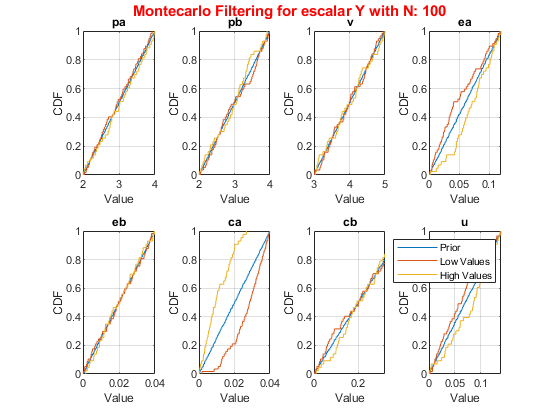

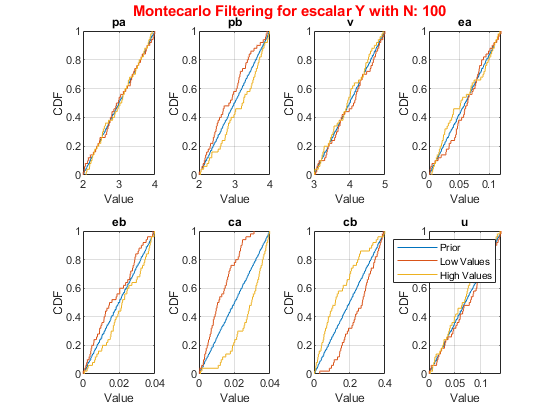

M= gsua_dmatrix(T,100);
Y = gsua_ua(M,T);

**Linealización**

T.clase=[3 3 4 0.06 0.02 0.02 0.2 0.07]'

T = 8×3 table
            Range      Nominal    clase
          _________    _______    _____

    pa    2       4        3         3 
    pb    2       4        3         3 
    v     3       5        4         4 
    ea    0    0.12     0.06      0.06 
    eb    0    0.04     0.02      0.02 
    ca    0    0.04     0.02      0.02 
    cb    0     0.4      0.2       0.2 
    u     0    0.14     0.07      0.07 


ymodel=gsua_eval(T.clase,T,0:0.1:300);%comprobamos la respuesta del sistema

nom=T.clase;
u_nominal=0.07;%entrada nominal

Mdis=T.clase.*ones(1,101)+u_nominal*(-1:0.02:1).*[0 0 0 0 0 0 0 1]'

Mdis =     3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000
    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000  

Progress: 100%
Estimated processing time (h:m:s): 0:0:28
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:28
Estimated stop time (h:m:s): 11:6:9
Number of simulations: 101


y=gsua_eval(Mdis,T,0:0.1:300);

yss1=y(:,end,1);
yss2=y(:,end,2);
yss3=y(:,end,3);

uin=u_nominal*(-1:0.02:1)+u_nominal;
figure(7)
subplot(1,3,1)
plot(uin,yss1)
legend('Estado 1')
xlabel('U [1/tiempo]')
ylabel('x1')

subplot(1,3,2)
plot(uin,yss2)
legend('Estado 2')
xlabel('U [1/tiempo]')
ylabel('x2')

subplot(1,3,3)
plot(uin,yss3)
legend('Estado 3')
xlabel('U [1/tiempo]')
ylabel('x3')

uin=u_nominal*(-1:0.02:1)+u_nominal;
figure(8)
plot(uin,yss1)
hold on 
plot(uin,yss2) 
hold on 
plot(uin,yss3)
legend({'Estado 1', 'Estado 2', 'Estado 3'})
xlabel('U [1/tiempo]')

syms x_1 x_2 x_3 ea eb ca cb u
ode1=  ca*x_1*x_3 -(ea+u)*x_1 + ca*x_1*x_2

$$ode1 = \mathrm{ca}\,x_{1}\,x_{2}-x_{1}\,\left(\mathrm{ea}+u\right)+\mathrm{ca}\,x_{1}\,x_{3}$$

ode2=  cb*x_2*x_3 -eb*x_2 -ca*x_1*x_2

$$ode2 = \mathrm{cb}\,x_{2}\,x_{3}-\mathrm{ca}\,x_{1}\,x_{2}-\mathrm{eb}\,x_{2}$$

ode3=  -ca*x_1*x_3 +(ea+u)*x_1 - cb*x_2*x_3 + eb*x_2

$$ode3 = x_{1}\,\left(\mathrm{ea}+u\right)+\mathrm{eb}\,x_{2}-\mathrm{ca}\,x_{1}\,x_{3}-\mathrm{cb}\,x_{2}\,x_{3}$$

ode4= x_1+x_2+x_3 -sum(T.Nominal(1:3))

$$ode4 = x_{1}+x_{2}+x_{3}-10$$

odes1= [ode1; ode2; ode3; ode4]

$$odes1 = \left(\begin{array}{c} \mathrm{ca}\,x_{1}\,x_{2}-x_{1}\,\left(\mathrm{ea}+u\right)+\mathrm{ca}\,x_{1}\,x_{3}\\ \mathrm{cb}\,x_{2}\,x_{3}-\mathrm{ca}\,x_{1}\,x_{2}-\mathrm{eb}\,x_{2}\\ x_{1}\,\left(\mathrm{ea}+u\right)+\mathrm{eb}\,x_{2}-\mathrm{ca}\,x_{1}\,x_{3}-\mathrm{cb}\,x_{2}\,x_{3}\\ x_{1}+x_{2}+x_{3}-10 \end{array}\right)$$

odes=subs(odes1,{'ea' 'eb' 'ca' 'cb' 'u'}, T.Nominal(4:end)')

$$odes = \left(\begin{array}{c} \frac{x_{1}\,x_{2}}{50}-\frac{13\,x_{1}}{100}+\frac{x_{1}\,x_{3}}{50}\\ \frac{x_{2}\,x_{3}}{5}-\frac{x_{1}\,x_{2}}{50}-\frac{x_{2}}{50}\\ \frac{13\,x_{1}}{100}+\frac{x_{2}}{50}-\frac{x_{1}\,x_{3}}{50}-\frac{x_{2}\,x_{3}}{5}\\ x_{1}+x_{2}+x_{3}-10 \end{array}\right)$$

vars = [x_1 x_2 x_3];
sol=solve(odes==0,vars)

sol = struct with fields:
    x_1: [4×1 sym]
    x_2: [4×1 sym]
    x_3: [4×1 sym]


double([sol.x_1,sol.x_2,sol.x_3])

ans =          0         0   10.0000
    3.5000         0    6.5000
         0    9.9000    0.1000
    3.5000    6.0500    0.4500


ynom=gsua_eval(T.clase,T,0:300);

ynom(end,end,:)

ans = ans(:,:,1) =

    3.5000


ans(:,:,2) =

    6.0487


ans(:,:,3) =

    0.4513


ja1=jacobian(odes,vars)

$$ja1 = \left(\begin{array}{ccc} \frac{x_{2}}{50}+\frac{x_{3}}{50}-\frac{13}{100} & \frac{x_{1}}{50} & \frac{x_{1}}{50}\\ -\frac{x_{2}}{50} & \frac{x_{3}}{5}-\frac{x_{1}}{50}-\frac{1}{50} & \frac{x_{2}}{5}\\ \frac{13}{100}-\frac{x_{3}}{50} & \frac{1}{50}-\frac{x_{3}}{5} & -\frac{x_{1}}{50}-\frac{x_{2}}{5}\\ 1 & 1 & 1 \end{array}\right)$$

ja1= subs(ja1, {'x_1' 'x_2' 'x_3'}, {3.5, 6.0487,0.4513})

$$ja1 = \left(\begin{array}{ccc} 0 & \frac{7}{100} & \frac{7}{100}\\ -\frac{60487}{500000} & \frac{13}{50000} & \frac{60487}{50000}\\ \frac{60487}{500000} & -\frac{3513}{50000} & -\frac{63987}{50000}\\ 1 & 1 & 1 \end{array}\right)$$

ja2=jacobian(odes1,u)

$$ja2 = \left(\begin{array}{c} -x_{1}\\ 0\\ x_{1}\\ 0 \end{array}\right)$$

ja2= subs(ja2,{'x_1'}, {3.5})

$$ja2 = \left(\begin{array}{c} -\frac{7}{2}\\ 0\\ \frac{7}{2}\\ 0 \end{array}\right)$$

A=double(ja1)

A =          0    0.0700    0.0700
   -0.1210    0.0003    1.2097
    0.1210   -0.0703   -1.2797
    1.0000    1.0000    1.0000


B=double(ja2)

B =    -3.5000
         0
    3.5000
         0


A= A(1:3,:)

A =          0    0.0700    0.0700
   -0.1210    0.0003    1.2097
    0.1210   -0.0703   -1.2797


B= B(1:3)

B =    -3.5000
         0
    3.5000


eig(A)

ans =    -1.2095
   -0.0000
   -0.0700


MC= [B A*B A^2*B]

MC =    -3.5000    0.2450   -0.0172
         0    4.6575   -5.9592
    3.5000   -4.9025    5.9763


McInv= inv(MC)

McInv = 1.0e+15 *

    0.0953    0.0953    0.0953
    1.4406    1.4406    1.4406
    1.1259    1.1259    1.1259


## **Control**

**Función de Transferencia SISO**

syms s t
G=[1 0 0]*inv(s*eye(3)-A)*B

$$G = \frac{49}{2\,\left(100\,s^{2}+7\,s\right)}-\frac{7}{2\,s}$$

[Pn,Pd]=numden(G)

$$Pn = -350$$

$$Pd = 100\,s+7$$

syms k
Pch=Pd+k*Pn

$$Pch = 100\,s-350\,k+7$$

**CONTROL MIMO**

K = place(A,B,[-100,-150,-220])

Unrecognized function or variable 'A'.

**Análisis de Sensibilidad**

close_system('modeloLineales')
clear; clc
model = 'modeloLineales';
ParIn = {'pa','pb','v','ea','eb','ca','cb','u'};
p=30

p = 30

Ranges = [ 2 p; 2 p; 3 p; 0.001 p; 0.001 p; 0.001 p; 0.001 p; 0.001 p];
out_names = {'Fracción de A','Fracción de B', 'Fracción no ocupada' };
[T2 Time2] = gsua_dataprep(model,Ranges,ParIn,'out_names',out_names,'rMethod','percent');

Setting environment to work with simulink
Setting nominal values
All done!


T2.Properties.CustomProperties.output=1

T2 = 8×2 table
               Range          Nominal
          ________________    _______

    pa       1.4       2.6         2 
    pb       1.4       2.6         2 
    v        2.1       3.9         3 
    ea    0.0007    0.0013     0.001 
    eb    0.0007    0.0013     0.001 
    ca    0.0007    0.0013     0.001 
    cb    0.0007    0.0013     0.001 
    u     0.0007    0.0013     0.001 


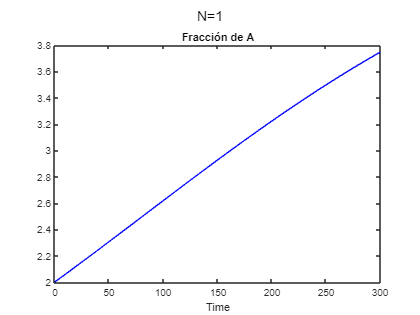

ynom2 =     2.0000    2.0060    2.0120    2.0181    2.0241    2.0301    2.0361    2.0422    2.0482    2.0543    2.0603    2.0664    2.0724    2.0785    2.0846    2.0907    2.0967    2.1028    2.1089    2.1150    2.1211    2.1272    2.1334    2.1395    2.1456    2.1517    2.1578    2.1640    2.1701    2.1763    2.1824    2.1886    2.1947    2.2009    2.2070    2.2132    2.2194    2.2255    2.2317    2.2379    2.2441    2.2503    2.2564    2.2626    2.2688    2.2750    2.2812    2.2874    2.2936    2.2999


ynom2= gsua_eval(T2.Nominal,T2)

M3= gsua_dmatrix(T2,100);

Tsa= gsua_sa(M3,T2,'parallel',false, 'SensMethod','Saltelli','ynom',ynom2)

Progress: 10%
Estimated processing time (h:m:s): 0:2:21
Remaining time (h:m:s): 0:2:6
Elapsed time (h:m:s): 0:0:14
Estimated stop time (h:m:s): 17:31:27
Number of simulations: 500
Progress: 20%
Estimated processing time (h:m:s): 0:2:17
Remaining time (h:m:s): 0:1:49
Elapsed time (h:m:s): 0:0:27
Estimated stop time (h:m:s): 17:31:23
Number of simulations: 500
Progress: 30%
Estimated processing time (h:m:s): 0:2:14
Remaining time (h:m:s): 0:1:33
Elapsed time (h:m:s): 0:0:40
Estimated stop time (h:m:s): 17:31:20
Number of simulations: 500
Progress: 40%
Estimated processing time (h:m:s): 0:2:16
Remaining time (h:m:s): 0:1:21
Elapsed time (h:m:s): 0:0:54
Estimated stop time (h:m:s): 17:31:22
Number of simulations: 500
Progress: 50%
Estimated processing time (h:m:s): 0:2:15
Remaining time (h:m:s): 0:1:7
Elapsed time (h:m:s): 0:1:7
Estimated stop time (h:m:s): 17:31:21
Number of simulations: 500
Progress: 60%
Estimated processing time (h:m:s): 0:2:16
Remaining time (h:m:s): 0:0:54
Elapsed tim

Tsa = 8×6 table
               Range          Nominal        Si           STi          STi_vec          Si_vec   
          ________________    _______    __________    __________    ____________    ____________

    pa       1.4       2.6         2       -0.15967       0.52175    1×301 double    1×301 double
    pb       1.4       2.6         2       -0.17092       0.25753    1×301 double    1×301 double
    v        2.1       3.9         3       -0.21633       0.38918    1×301 double    1×301 double
    ea    0.0007    0.0013     0.001      -0.024928      0.031114    1×301 double    1×301 double
    eb    0.0007    0.0013     0.001     -3.143e-16    9.7736e-31    1×301 double    1×301 double
    

sum(Tsa.Si)/sum(abs(Tsa.Si))

ans = -1.0000

%indice de confiabilidad mayor 0.95

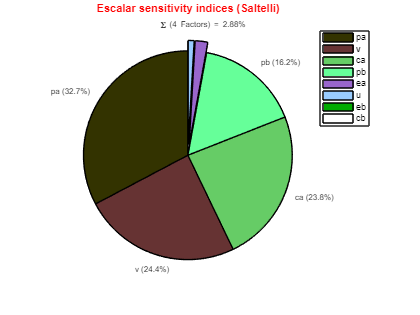

figure(9)
gsua_plot('Pie',Tsa,Tsa.STi)

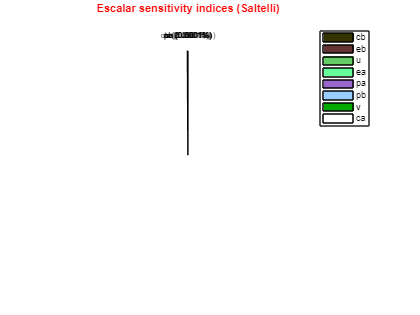

figure(10)
gsua_plot('Pie',Tsa, Tsa.Si)

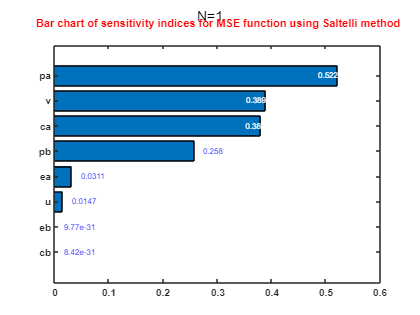

figure(11)
gsua_plot('Bar',Tsa,Tsa.STi)

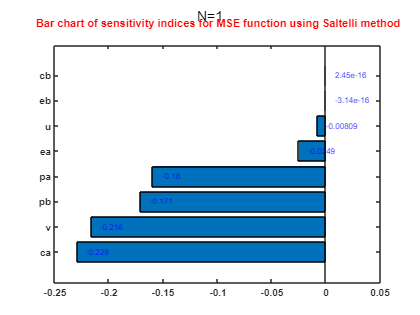

figure(12)
gsua_plot('Bar',Tsa,Tsa.Si)